# Blend Mode experiments

Goal: define a "realistic" modification axis by blending the information of the drawing and the photo

Methods: Overlay blend mode

clear all;
close all;

## 0) Import the data

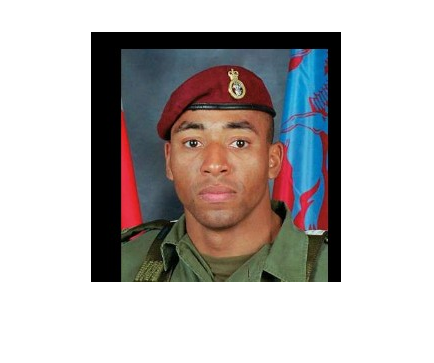

% import the data
%im = im2double(imread('../lfw/Avril_Lavigne_0001.jpg'));
%im = im2double(imread('../lfw/Ai_Sugiyama_0002.jpg'));
im = im2double(imread('../lfw/Ainsworth_Dyer_0001.jpg'));
%im = im2double(imread('../lfw/Alejandro_Toledo_0003.jpg'));
%im = im2double(imread('../lfw/Allyson_Felix_0003.jpg'));
imshow(im)

## Build drawing

% hyperparameters
thresh = 0.2; % threshold for edge detection
k = 2; % size of dilatation structuring element
n_cluster = 4; % number of output colors
gamma = 0.5; % color adjustement
isLAB = true; % space in which to perform the clustering

level = 0.5; % color of edges
sigma_color = 0.1; % std for color smoothering
amplitude = 1; % importance of color gradient
sigma_g = 5; % std for color gradient

% drawing
im_draw = blending_baseline(im, thresh, k, n_cluster, gamma, isLAB, level, sigma_color, amplitude, sigma_g);

## Blend modes

Screen

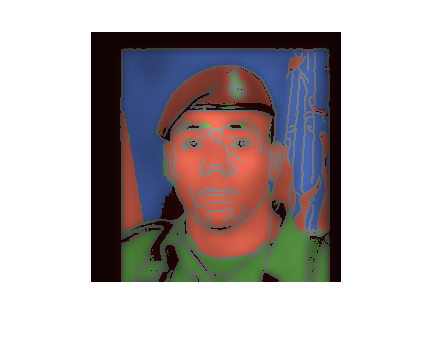

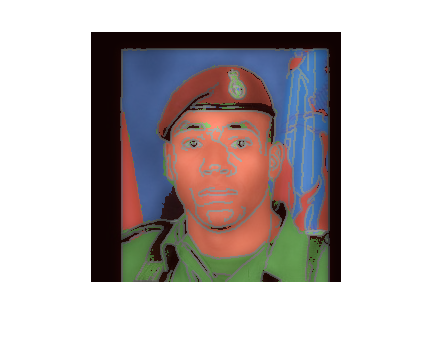

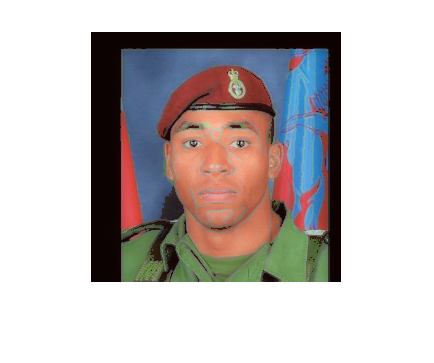

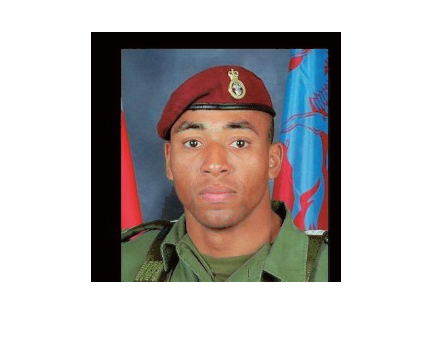

% hyperparameters
for lambda = 0:0.25:1
    % screen blend mode
    im_blend = 1 - (1 - (1-lambda)*im_draw).*(1 - lambda*im);
    % normalization
    im_blend = im_blend / max(im_blend(:));
    % display results
    figure
    imshow(im_blend)
end